# **IO611 - CAN HS Loopback **

This example shows how to run a simple loopback using the IO611 I/O module. The IO611 features 2 isolated channels for high- and low-speed CAN (CAN HS and LS) as well as two LIN interfaces. The Simulink model implements a bidirectional CAN HS loopback transmitting and receiving data between channel 1 and channel 2.

This example demonstrates the following modes and features:

- Communication between a pair of channels on an IO611 I/O module 

- **Single Read from Buffer (FIFO)** receiving mode

- **Specify by IDs** receiving mode

- Using the CAN Pack and CAN Unpack blocks with **Raw Data** mode

- Using the CAN Pack and CAN Unpack blocks with **Manually Specified Signals** mode

- Using the CAN Pack and CAN Unpack blocks using **CANdb Specified Signals** mode

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO611 I/O module installed

- 1x 9-pin D-sub to 9-pin D-sub loopback cable

### Connection Diagram

For this example, connect CAN channel 1 and channel 2 in a loopback configuration. Refer to the diagram below for the necessary pin wiring and termination resistors. A loopback cable, included with the system, can also be used.

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO611_CAN_HS_Loopback';
open_system(modelName);

## Model Description

The Simulink model is split into two subsystems that represent the bidirectional CAN communication. One subsystem is used to send CAN messages from channel 1 to channel 2 and the second subsystem in the other direction.

### Sending Data from Channel 1 to Channel 2

 
% open Ch1Tx_Ch2Rx subsystem
speedgoat.model.highlight([modelName '/Ch1Tx_Ch2Rx'],'Open',true);

In this subsystem, on the left-hand side, six signals are packed into three CAN messages using different modes of the [CAN Pack](https://mathworks.com/help/slrealtime/io_ref/canpack.html) block. The messages are concatenated to form an array of buses of the CAN_MESSAGE_BUS data type, which are connected to the [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_2_write) block. In the CAN Write block, the **Number of Messages **is set to 3 to match the size of the input array.  

On the right-hand side, the expected **CAN ID**s are specified in the [CAN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_2_read) block mask. Consequently the three IDs are available as outputs. The CAN messages are unpacked using [CAN Unpack](https://mathworks.com/help/slrealtime/io_ref/canunpack.html) blocks that are configured in different modes, similarly to the transmitting side.

Let us now consider the three modes used in the CAN Pack and CAN Unpack blocks in more detail.

#### Signals Specified in a dbc File

 
% open CAN pack block configured for . dbc file
speedgoat.model.highlight([modelName '/Ch1Tx_Ch2Rx/CANPack_Database'],'Open',true);

When selecting to input/output data as** CANdb specified signals** in the block mask, the user is prompted to select a *.dbc file. They must then select which message and which signals are to be sent or received. When applying the changes, the number of block ports and the corresponding labels are configured accordingly. 

#### Manually S**pecified S**ignals

 
% open CAN pack block configured for manually specified signals
speedgoat.model.highlight([modelName '/Ch1Tx_Ch2Rx/CANPack_ManualSignals'],'Open',true);

The selection **Manually Specified Signals** allows users to define the signals of the specified CAN ID using the **Signals** table. The number of block inputs depends on the number of signals specified in this table. 

As is the case when dbc files are used, the data type and size should be handled according to the signal configuration.

#### RAW Data

 
% open CAN pack block configured for raw data
speedgoat.model.highlight([modelName '/Ch1Tx_Ch2Rx/CANPack_RawData'],'Open',true);

When selecting **Raw Data** in the CAN Pack and CAN Unpack block mask, the user must configure parameters such as the **CAN Identifier**, **Identifier Type**, and **Length (bytes)** of the transmitted data. The CAN Pack block now expects an array of bytes corresponding to the size of the data length defined in the block mask. This array can be created using a [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) block. On the receiving side, the CAN Unpack block outputs the data as uint8 and this array of bytes can be converted with a [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) block into the required datatype. 

### Sending Data from Channel 2 to Channel 1

 
% open Ch1Rx_Ch2Tx subsystem
speedgoat.model.highlight([modelName '/Ch1Rx_Ch2Tx'],'Open',true);

In this subsystem, the CAN messages are sent from CAN channel 2 to channel 1. The difference here is that the receiving channel 1 is configured to use the **Single Read from Buffer (FIFO)** mode in the CAN Read block. For the sending side, multiple signals are packed into two CAN messages using the CAN Pack block and the signals are manually specified. 

#### Single Read from Buffer (FIFO) 

The receiving mode of the CAN Read block is set to **Single Read from Buffer (FIFO)**. When using this mode, all CAN messages that are available on the specified CAN channel are stored in a message queue, which is implemented as a First-In-First-Out (FIFO) buffer. In this mode, the CAN Read block has direct access to this buffer, and if there are messages in the message queue, the **Data Present** outport will be 1. With every execution of the CAN Read block, one single message is read from the queue and output on the **CAN Msg** output port.

 
% highlight "Single Read from Buffer (FIFO)" option in the CAN read block
speedgoat.model.highlight([modelName '/Ch1Rx_Ch2Tx/CAN_Ch1_ReadLoop/CANRead FIFO'],'Parameter','HasMulRead');

To ensure that the complete receive buffer is processed and emptied in one sample step, the CAN Read block must be executed multiple times until the **Data Present** outport indicates that there are no messages remaining in the queue. This can be achieved with a do-while subsystem construction, which will result in multiple iterations of the complete subsystem. Consequently, every CAN message that has been read from the bus can be processed individually and the complete buffer is cleared in every sample step.

 
% highlight While Iterator Subsystem for channel 1
speedgoat.model.highlight([modelName '/Ch1Rx_Ch2Tx/CAN_Ch1_ReadLoop']);

#### Inside the While Iterator Subsystem         

 
% open While Iterator Subsystem for channel 1
speedgoat.model.highlight([modelName '/Ch1Rx_Ch2Tx/CAN_Ch1_ReadLoop/While Iterator'],'Open',true);

The maximum number of iterations is set in the [While Iterator](https://mathworks.com/help/simulink/slref/whileiterator.html) block in the Simulink/Ports & Subsystem library. This can be set to unlimited iterations with (-1), but in reality, it is best practice to set a limit of 500 iterations.

Inside the subsystem, multiple CAN Unpack blocks can be directly connected to the **CAN Msg** output port. The matching IDs are then unpacked into the signals of the message and can be routed out of the subsystem. In this example, a [Bus Creator](https://mathworks.com/help/simulink/slref/buscreator.html) block is used to combine all the signals of one CAN ID into a Simulink bus signal. It is recommended to use buses for routing when working with multiple CAN messages received as this improves the overview of the Simulink model. 

If multiple messages with the same **CAN Identifier** are received, only the most recent messages will appear in the do-while subsystem output. When every single CAN message from the CAN bus must be processed, the sample time of the subsystem can be increased, or the processing algorithm can be included in the While Iterator Subsystem.

The sample time of the subsystem is defined by Simulink inheritance rules: If the subsystem does not have input ports, it will inherit the fundamental sample time of the model. Alternatively, the sample time of the subsystem can be controlled by adding an input port. This is done by using a connected signal that has a defined sample time. The sample time must be chosen depending on the bus load in order to avoid buffer overflow during one sample step.

 
% highlight sample time of Constant block
speedgoat.model.highlight([modelName '/Ch1Rx_Ch2Tx/Ch1Rx'],'Parameter','SampleTime');

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download the real-time application to the target machine and set stop time
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   
set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Wait until the real-time application reaches the stop time of 10 seconds

### Results

During the simulation, open the Simulink scopes or use SDI to view the data. The output should look as follows:

#### Ch1Tx_Ch2Rx

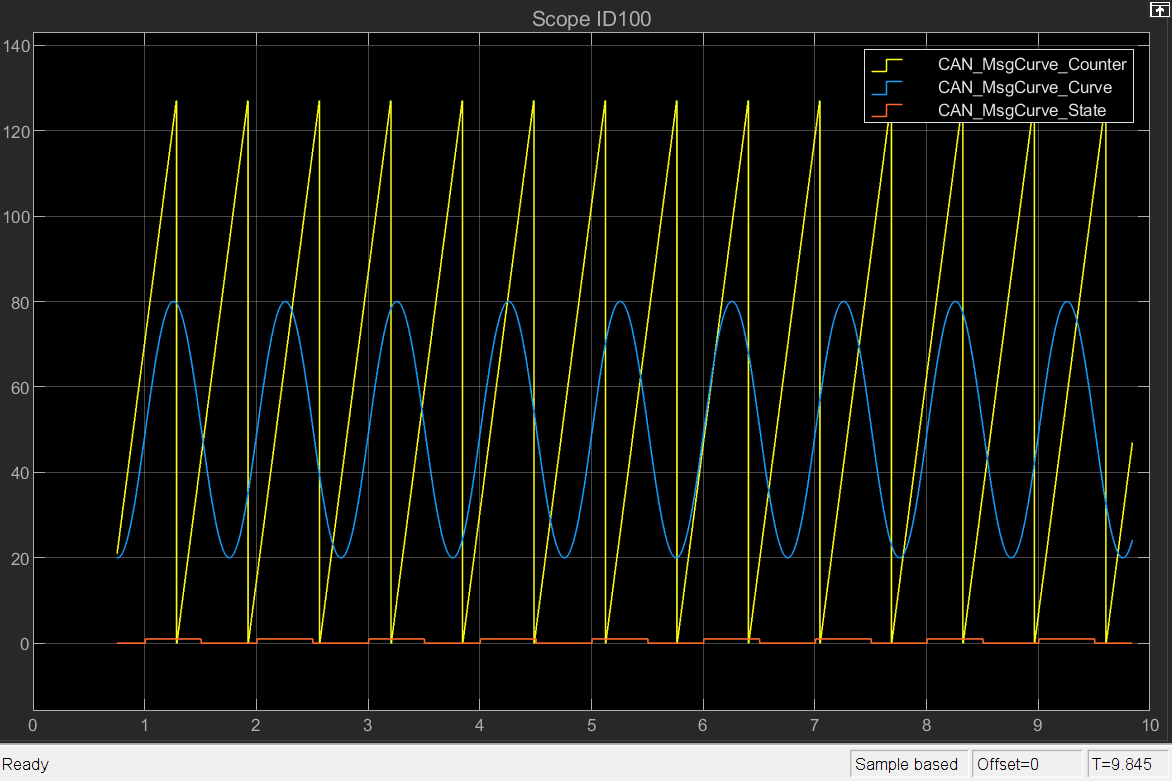

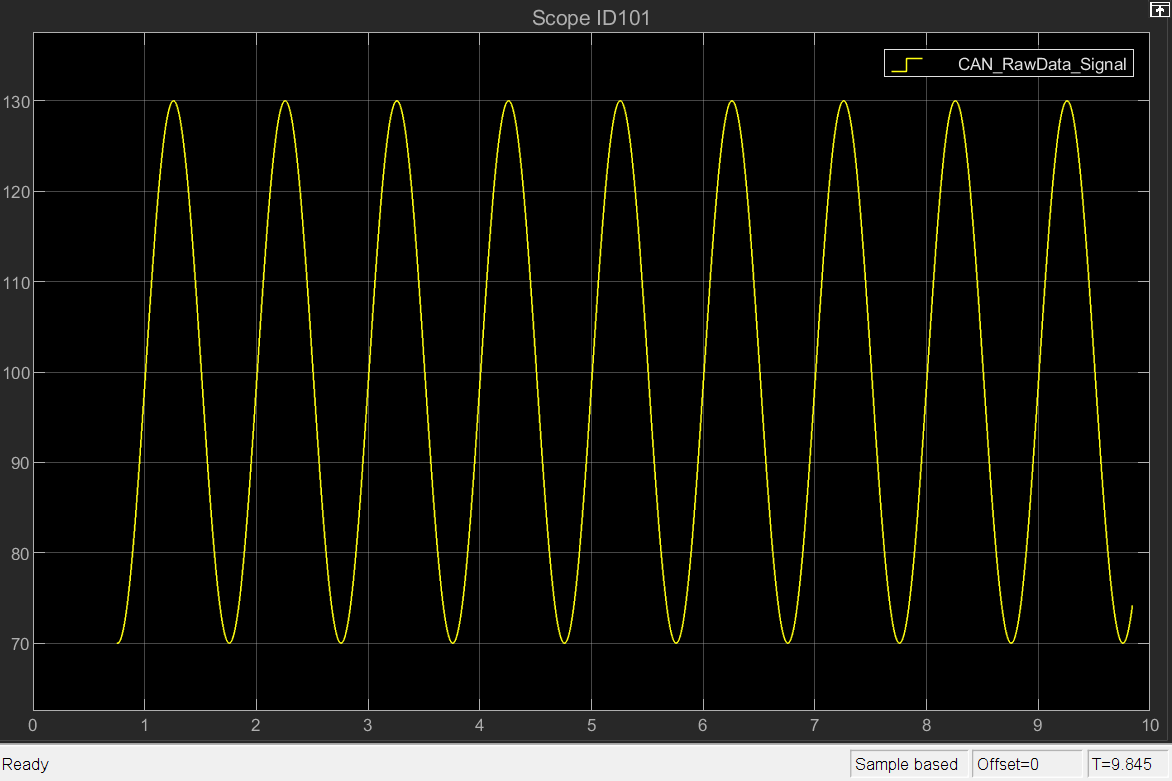

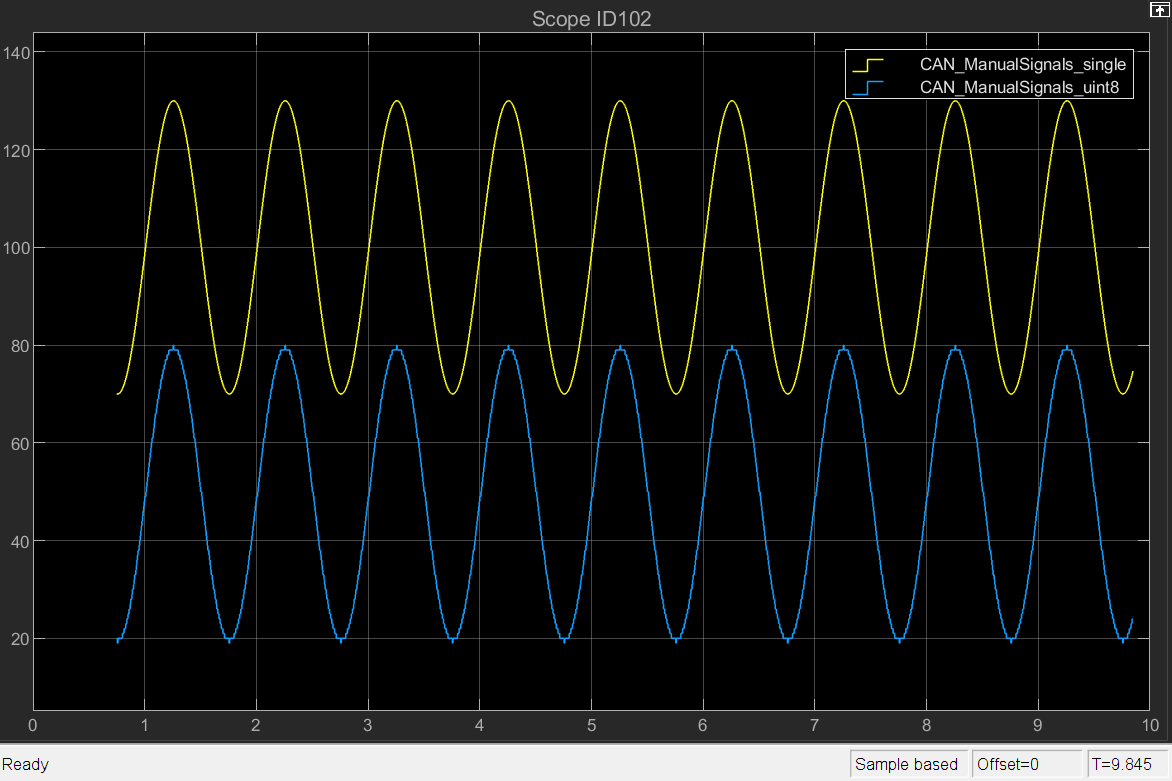

#### Ch1Rx_Ch2Tx

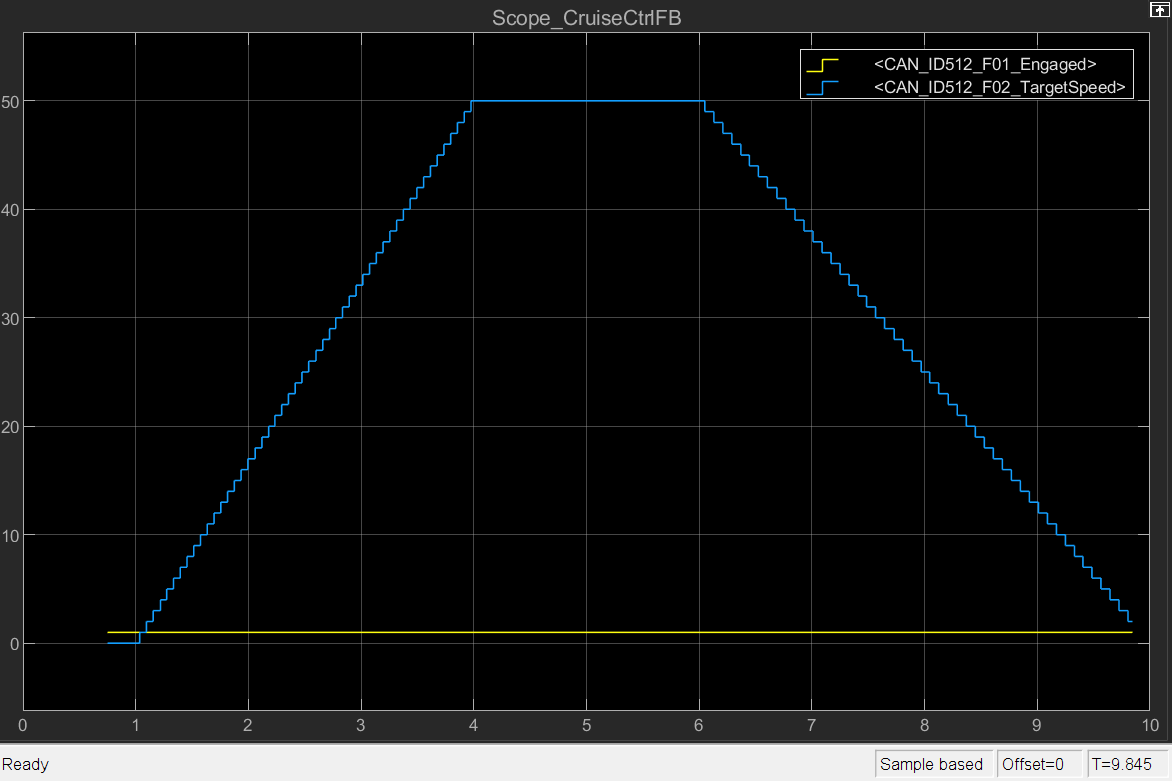

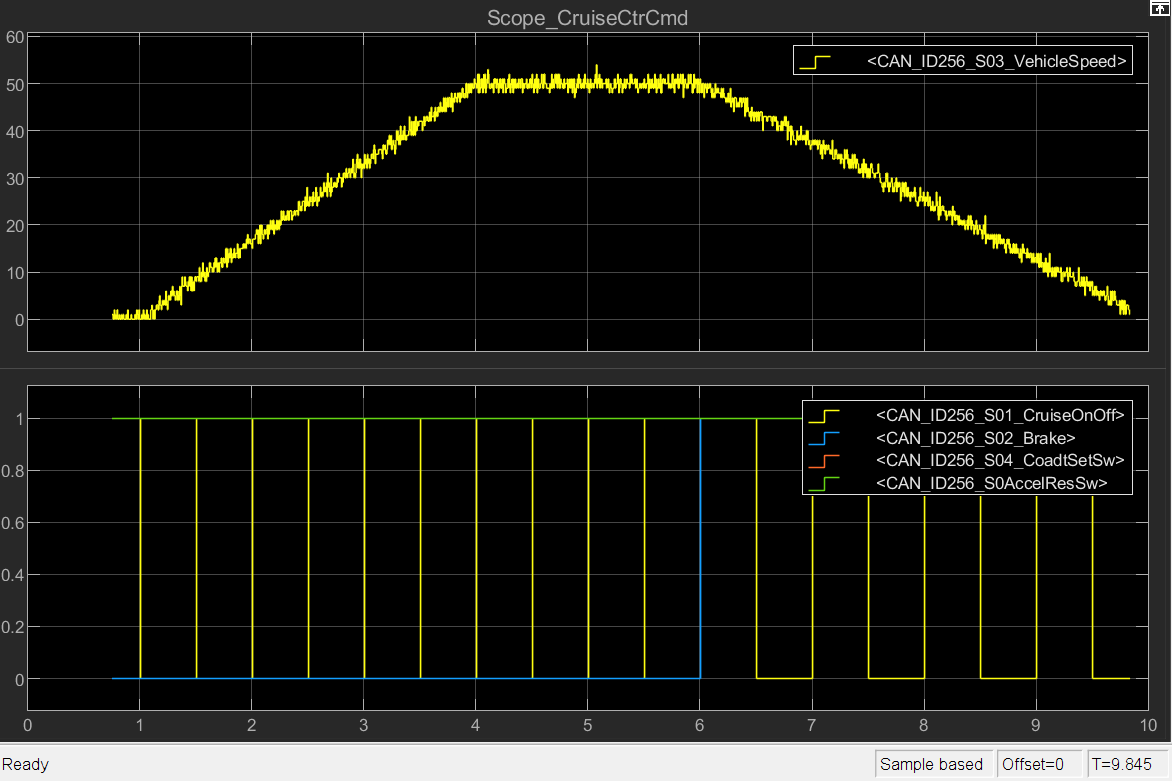

## Additional References

- [IO611 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_2)